% define sampling parameters
f = [480,500,530,570,600, 900, 1200]

f =          480         500         530         570         600         900        1200


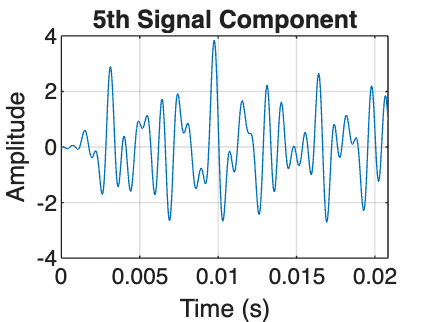

T1 = 1/480;
Fs = 100e6;
dt = 1/Fs;
t_array = 0:dt:10*T1;

% define amplitude and phase
amp = getWin(9, 'Gaussian');

phase = linspace(0, 2*pi, 9).';

% create signals and plot


cw_signal = createCWSignals(t_array, f(1), amp, phase);
for i = 2:length(f)
    cw_signal = cw_signal + createCWSignals(t_array, f(i), amp, phase);
end


% Extract the 5th signal
% Assuming cw_signal is organized with signals as rows
fifth_signal = cw_signal(5, :); % If signals are in rows

% Plot the 5th signal
figure;
plot(t_array, fifth_signal);
title('5th Signal Component');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

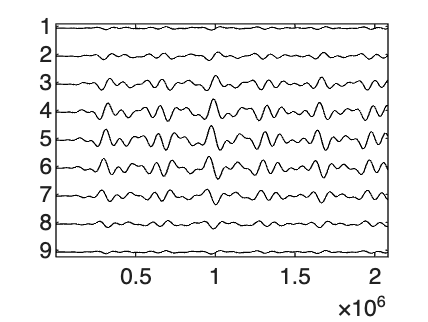



stackedPlot(cw_signal);

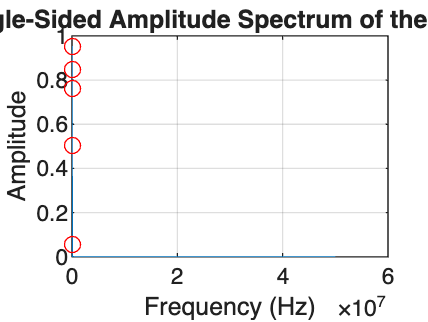


% Compute the FFT of the resulting signal
n = length(cw_signal(5, :));
Y = fft(cw_signal(5, :));
P2 = abs(Y/n); % Two-sided spectrum
P1 = P2(1:n/2+1); % Single-sided spectrum
P1(2:end-1) = 2*P1(2:end-1); % Energy of negative spectrum is folded onto the positive spectrum

f_fft = Fs*(0:(n/2))/n;

% Find peaks in the FFT result
[peaks, locs] = findpeaks(P1, 'MinPeakHeight', 0.01*max(P1));

% Plot the amplitude spectrum
figure;
plot(f_fft, P1);
hold on;
plot(f_fft(locs), peaks, 'ro');
title('Single-Sided Amplitude Spectrum of the Signal');
xlabel('Frequency (Hz)');
ylabel('Amplitude');
grid on;


% Calculate average amplitude of the peaks
avg_amplitude = mean(peaks);

% Display average amplitude
disp(['Average Amplitude of Peaks: ', num2str(avg_amplitude)]);

Average Amplitude of Peaks: 0.62448



rms_amplitude = sqrt(mean(fifth_signal.^2));
disp(['Root mean square amp: ', num2str(rms_amplitude)]);

Root mean square amp: 1.2256



std_amplitude = (max(fifth_signal) - min(fifth_signal)) / 2;
disp(['std_amp:',num2str(std_amplitude)]);

std_amp:3.2735
